## Frequency Analysis

Bode plot (MATLAB) vs Simcape

% input signal
m  = 3.600;     % kg
k  = 400;    % N/m
b  = 10;      % Ns/m
x0 = 0; % m
open_system("ssc_mass_spring_damper_v3")


% simulate single point
F_mag = 200; % N; input amplitude 
F_frq = 10;  % rad/s; input freq

% simulate lots of points
F_frq_vec = 10.^[0:0.1:2];
XF_mag = zeros(size(F_frq_vec));
for i = 1:length(F_frq_vec)
  F_frq = F_frq_vec(i);
  sim("ssc_mass_spring_damper_v3");
  t = simlog.Spring.x.series.time;
  X = simlog.Spring.x.series.values('m');
  F = simlog.Ideal_Force_Source.S.series.values('N');
  XF_mag(i) = rms(X(t>10))/rms(F(t>10));
end

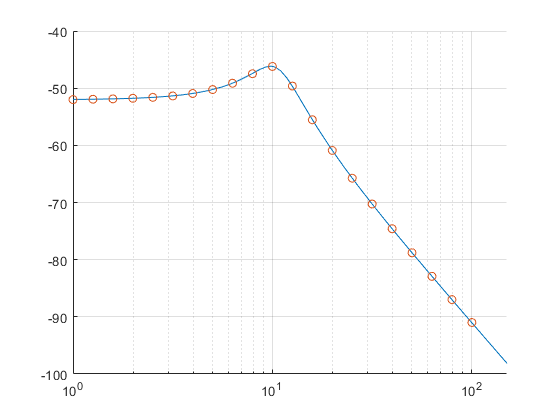

% TF in MATLAB & Bode
H = tf([1],[m b k]);
[mag,phase,wout] = bode(H);
mag = squeeze(mag);
phase = squeeze(phase);

figure(201); clf;
hold on
plot(wout,log10(mag)*20)
h = gca;
h.XScale = 'log';
grid on;
scatter(F_frq_vec,log10(XF_mag)*20)
xlim([1 150])

*Copyright 2021 The MathWorks, Inc.*